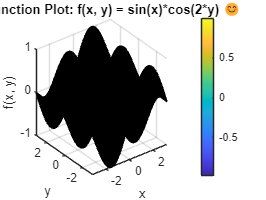

% 🌟✨🖥️ MATLAB Code by Seyed Mohammad Sajadi 🖥️✨🌟
% Student Number: 402448040

% Define the function
f = @(x, y) sin(x) .* cos(2*y);

% Generate x and y values
x = linspace(-pi, pi, 100);
y = linspace(-pi, pi, 100);

% Create a meshgrid from x and y
[x, y] = meshgrid(x, y);

% Evaluate the function at each point in the meshgrid
z = f(x, y);

% Create a 3D plot
figure;
surf(x, y, z);
title('😊 Function Plot: f(x, y) = sin(x)*cos(2*y) 😊');
xlabel('x');
ylabel('y');
zlabel('f(x, y)');

colorbar

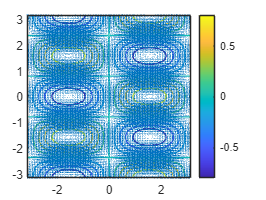

[px,py] = gradient(z);

figure
contour(x,y,z)
hold on
quiver(x,y,px,py)
hold off

colorbar

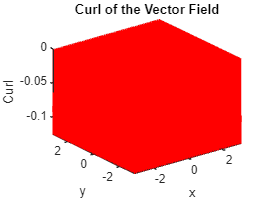

% Define the function components
F1 = @(x, y) sin(x) * cos(2*y);
F2 = @(x, y) sin(x) * cos(2*y);

% Define the partial derivatives
dF2_dx = @(x, y) 0; % Partial derivative of F2 with respect to x
dF1_dy = @(x, y) -2 * sin(x) * sin(2*y); % Partial derivative of F1 with respect to y

% Create a meshgrid for x and y values
[x, y] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);

% Evaluate the partial derivatives at each point
dF2_dx_values = dF2_dx(x, y);
dF1_dy_values = dF1_dy(x, y);

% Calculate the curl
curl_values = dF2_dx_values - dF1_dy_values;

% Plot the curl in 3D
figure;
quiver3(x, y, zeros(size(curl_values)), zeros(size(curl_values)), zeros(size(curl_values)), curl_values, 'r'); % Plot the curl vectors
title('Curl of the Vector Field');
xlabel('x');
ylabel('y');
zlabel('Curl');
axis tight;
view(3); % Set the view to 3D

% Define the vector field function
f = @(x, y) sin(x) .* cos(2*y);

% Define the range for x and y
x = linspace(-pi, pi, 20);
y = linspace(-pi, pi, 20);

% Create a grid of points
[X, Y] = meshgrid(x, y);

% Compute the curl of the vector field
P = f(X, Y);
Q = zeros(size(P));
[px, py] = gradient(P);
[qx, qy] = gradient(Q);
curl = qx - py;

% Plot the curl using quiver
quiver(X, Y, -py, qx);
xlabel('x');
ylabel('y');
title('Curl of the Vector Field');
axis tight;
axis square;



% Define the scalar function
f = @(x, y) sin(x) .* cos(2*y);

% Define the grid
x = linspace(-2*pi, 2*pi, 50);
y = linspace(-2*pi, 2*pi, 50);
[X, Y] = meshgrid(x, y);

% Compute the gradient of the scalar field
[grad_x, grad_y] = gradient(f(X, Y), x, y);

% Compute the curl of the gradient
curl_U = grad_y - grad_x;

% Plot the vector field and its curl
figure;

% Plot the vector field
subplot(1, 2, 1);
quiver(X, Y, grad_x, grad_y, 'AutoScale', 'on');
title('Gradient of Scalar Field');

% Plot the curl of the vector field
subplot(1, 2, 2);
contourf(X, Y, curl_U, 20, 'LineColor', 'none');
colorbar;
title('Curl of the Gradient Field');
